**AmirKabir University of Technology (Tehran Polytechnic)**

**Multi-Variable Control Systems - Assignment 02**                  **Mohammad Azimi - 402123100**

# Q2-

    **Paper DOI: ****10.4172/2168-9695.1000126**

**Note: First Run the corresponing **`.m`** file to generate all the required variables for this script.**

## System Description

**Longitudinal State Variables:**

- **Longitudinal velocity (u)**: The velocity component along the longitudinal axis of the UAV.

- **Vertical velocity (w)**: The velocity component along the vertical axis of the UAV.

- **Pitch rate (q):** The rate of change of pitch angle of the UAV.

- **Altitude (h):** The altitude or height of the UAV above a reference point.

- **Pitch angle (θ):** The angle between the longitudinal axis of the UAV and the horizontal plane.

**Lateral State Variables:**

- **Lateral velocity (v):** The velocity component along the lateral axis of the UAV.

- **Roll rate (p):** The rate of change of roll angle of the UAV.

- **Yaw angle (ψ):** The angle between the heading direction of the UAV and a reference direction.

- **Yaw rate (r):** The rate of change of yaw angle of the UAV.

- **Bank angle (φ):** The angle between the lateral axis of the UAV and the horizontal plane.

**Longitudinal Input Variables:**

- **Elevator deflection (δe):** The control input that adjusts the pitch angle of the UAV by deflecting the elevator control surface.

- **Thrust control (δt): **The control input that regulates the thrust or engine power of the UAV.

**Lateral Input Variables:**

- **Aileron deflection (δa):** The control input that controls the roll motion of the UAV by deflecting the aileron control surface.

- **Rudder deflection (δr):** The control input that influences the yaw motion of the UAV by deflecting the rudder control surface.

**Longitudinal Output Variables:**

- **Longitudinal velocity (v):** The velocity component along the longitudinal axis of the UAV.

- **Angle of attack (α):** The angle between the relative airflow and the chord line of the UAV's wing.

- **Pitch rate (q):** The rate of change of pitch angle of the UAV.

- **Pitch angle (θ):** The angle between the longitudinal axis of the UAV and the horizontal plane.

- **Altitude (h):** The altitude or height of the UAV above a reference point.

**Lateral Output Variables:**

- **Lateral velocity (v):** The velocity component along the lateral axis of the UAV.

- **Bank angle (φ):** The angle between the lateral axis of the UAV and the horizontal plane.

- **Yaw angle (ψ):** The angle between the heading direction of the UAV and a reference direction.

- **Yaw rate (r):** The rate of change of yaw angle of the UAV.

The state equations of the system can be represented in matrix form as:


$$\dot{x} =Ax+Bu$$


where:

 $\dot{x}$ represents the derivative of the state vector  with respect to time.

$A$ is the state matrix, which describes how the states evolve over time,

 $B$ is the input matrix, which describes how the control inputs affect the system dynamics,

 $u$ represents the control input vector.

In this system:

- **State Matrix (A):**

The matrix  is a 10x10 matrix that defines the dynamics of the UAV system. Each element of this matrix represents the influence of one state on the rate of change of another state. For example, element  represents how state  influences the rate of change of state . In other words, the non-zero elements of this matrix indicate the interdependencies among different states of the system.

- **Input Matrix (B):**

The matrix  is a 10x3 matrix that defines how the control inputs affect the dynamics of the system. Each column corresponds to one control input, and each row corresponds to one state. For example, element  represents how control input  affects the rate of change of state .

The state equations encapsulate the dynamic behavior of the UAV system, describing how the system's states evolve over time in response to control inputs and external influences. These equations are fundamental for understanding and modeling the behavior of the UAV in various flight conditions and for designing control strategies to achieve desired performance objectives.

***Note***: The longitudonal and lateral dynamics of the system are coupled together with the following structure:


$$\mathbf{coupled}\;\mathbf{dynamics}\cong \left\lbrack \begin{array}{cc}
\mathbf{longitudinal}\;\mathbf{dynamics} & 0\\
0 & \mathbf{lateral}\;\mathbf{dynamics}
\end{array}\right\rbrack$$


## Transfer functions and Char Equations

for o=1:numOutputs  
    for i=1:numInputs
        fprintf("Transfer Function for Output_%d/Input_%d}= \n", o,i)
        eval(simplify(G(o,i)))
        fprintf("-------------------------------------------------------------\n")
    end
end

Transfer Function for Output_1/Input_1}= 


$$ans = \frac{103931830741478864956654892319928043438080000000000\,s^{4}+3121469489518594565991159974410976863606171943043072\,s^{3}+161594549648747308286085174068049629834716785347133440\,s^{2}+3144221676948938625490097397544364164827829108056522752\,s+117557541015456575362180753119740001096451288465408}{324518553658426726783156020576256000000000000000000\,s^{5}+7776892427292001451322264139497629286400000000000000\,s^{4}+81565903709617199449246752037131804412843183308800000\,s^{3}+50154898283829661681674033328966432400876136038400000\,s^{2}+41941713408875204174864245070215176257391715942400000\,s+24147242407981903647129354946849364809823027200000}$$

-------------------------------------------------------------


Transfer Function for Output_1/Input_2}= 


ans = 0

-------------------------------------------------------------


Transfer Function for Output_1/Input_3}= 


ans = 0

-------------------------------------------------------------


Transfer Function for Output_1/Input_4}= 


ans = 0

-------------------------------------------------------------


Transfer Function for Output_2/Input_1}= 


$$ans = -\frac{240635890362669980834737314079256269617155442827329536\,s^{4}+64795178390197296510302184839924074924275532142213070848\,s^{3}+292989776323005456016899031005803928871933452859813658624\,s^{2}+5027334507663137336532875535584046627768378323034540343296\,s+222712410648290284725151999644397317569240239563603968}{162259276829213363391578010288128000000000000000000\,s^{5}+3888446213646000725661132069748814643200000000000000\,s^{4}+40782951854808599724623376018565902206421591654400000\,s^{3}+25077449141914830840837016664483216200438068019200000\,s^{2}+20970856704437602087432122535107588128695857971200000\,s+12073621203990951823564677473424682404911513600000}$$

-------------------------------------------------------------


Transfer Function for Output_2/Input_2}= 


ans = 0

-------------------------------------------------------------


Transfer Function for Output_2/Input_3}= 


ans = 0

-------------------------------------------------------------


Transfer Function for Output_2/Input_4}= 


ans = 0

-------------------------------------------------------------


Transfer Function for Output_3/Input_1}= 


$$ans = -\frac{5\,s\,\left(10847032656032913342726989987761356800000000000\,s^{3}+86787523591651347868222915805574848734822400000\,s^{2}+53926355164459182935208055833203852942619181056\,s+6222991010580584998857469874099753240756224\right)}{405648192073033408478945025720320000000000000\,s^{5}+9721115534115001814152830174372036608000000000\,s^{4}+101957379637021499311558440046414755516053979136\,s^{3}+62693622854787077102092541661208040501095170048\,s^{2}+52427141761094005218580306337768970321739644928\,s+30184053009977379558911693683561706012278784}$$

-------------------------------------------------------------


Transfer Function for Output_3/Input_2}= 


ans = 0

-------------------------------------------------------------


Transfer Function for Output_3/Input_3}= 


ans = 0

-------------------------------------------------------------


Transfer Function for Output_3/Input_4}= 


ans = 0

-------------------------------------------------------------


Transfer Function for Output_4/Input_1}= 


$$ans = -\frac{54235163280164566713634949938806784000000000000\,s^{3}+433937617958256739341114579027874243674112000000\,s^{2}+269631775822295914676040279166019264713095905280\,s+31114955052902924994287349370498766203781120}{405648192073033408478945025720320000000000000\,s^{5}+9721115534115001814152830174372036608000000000\,s^{4}+101957379637021499311558440046414755516053979136\,s^{3}+62693622854787077102092541661208040501095170048\,s^{2}+52427141761094005218580306337768970321739644928\,s+30184053009977379558911693683561706012278784}$$

-------------------------------------------------------------


Transfer Function for Output_4/Input_2}= 


ans = 0

-------------------------------------------------------------


Transfer Function for Output_4/Input_3}= 


ans = 0

-------------------------------------------------------------


Transfer Function for Output_4/Input_4}= 


ans = 0

-------------------------------------------------------------


Transfer Function for Output_5/Input_1}= 


$$ans = -\frac{-138130989276837620285692822884549121802240000000\,s^{3}+6230805805045134652549546677440033239733924528128\,s^{2}+855186094888287007714920124186827944636989413785600\,s+497564573639544366457109865460479188656926951997440}{50706024009129176059868128215040000000000000000\,s^{5}+1215139441764375226769103771796504576000000000000\,s^{4}+12744672454627687413944805005801844439506747392000\,s^{3}+7836702856848384637761567707651005062636896256000\,s^{2}+6553392720136750652322538292221121290217455616000\,s+3773006626247172444863961710445213251534848000}$$

-------------------------------------------------------------


Transfer Function for Output_5/Input_2}= 


ans = 0

-------------------------------------------------------------


Transfer Function for Output_5/Input_3}= 


ans = 0

-------------------------------------------------------------


Transfer Function for Output_5/Input_4}= 


ans = 0

-------------------------------------------------------------


Transfer Function for Output_6/Input_1}= 


ans = 0

-------------------------------------------------------------


Transfer Function for Output_6/Input_2}= 


ans = 0

-------------------------------------------------------------


Transfer Function for Output_6/Input_3}= 


$$ans = -\frac{4140410611795277515421107229245658922286495825920000000\,s^{2}+45449232118956772681902193922331221347510654611750912000\,s+47757200035707431939096457774898597044934304364761186304}{212676479325586539664609129644855132160000000000000000\,s^{4}+4197723278336696885284189157278292656521216000000000000\,s^{3}+15667766852402643227934405072461101237232730112000000000\,s^{2}+50001543770014169084492277807465680233986354105548800000\,s+10282506429169271134893917852792828363919815754330931200}$$

-------------------------------------------------------------


Transfer Function for Output_6/Input_4}= 


$$ans = \frac{8290757623107770424351172793534553598512332800000000000\,s^{3}+2307297360114481369994350568073823064864019783352320000000\,s^{2}+34598826136752191516162074566940021016164395180401623040000\,s-5536567613950843154647189434284882974988941896190923898880}{26584559915698317458076141205606891520000000000000000000\,s^{4}+524715409792087110660523644659786582065152000000000000000\,s^{3}+1958470856550330403491800634057637654654091264000000000000\,s^{2}+6250192971251771135561534725933210029248294263193600000000\,s+1285313303646158891861739731599103545489976969291366400000}$$

-------------------------------------------------------------


Transfer Function for Output_7/Input_1}= 


ans = 0

-------------------------------------------------------------


Transfer Function for Output_7/Input_2}= 


ans = 0

-------------------------------------------------------------


Transfer Function for Output_7/Input_3}= 


$$ans = -\frac{665677380289085869150226575788396563660800000000000000\,s^{3}+2263426019987942144130696501757483042713108480000000000\,s^{2}+7005625050634536895349920597741769738419636797440000000\,s-174254938031613968416553884297063996819240692744192000}{4253529586511730793292182592897102643200000000000000\,s^{4}+83954465566733937705683783145565853130424320000000000\,s^{3}+313355337048052864558688101449222024744654602240000000\,s^{2}+1000030875400283381689845556149313604679727082110976000\,s+205650128583385422697878357055856567278396315086618624}$$

-------------------------------------------------------------


Transfer Function for Output_7/Input_4}= 


$$ans = -\frac{21301676169250747812807250425228690037145600000000000\,s^{3}+1316311756766515539456665413005594865813956853760000000\,s^{2}+18021325615585722780604482783729725165408866009088000000\,s-529336730053058799787808823497895796100198987666030592}{4253529586511730793292182592897102643200000000000000\,s^{4}+83954465566733937705683783145565853130424320000000000\,s^{3}+313355337048052864558688101449222024744654602240000000\,s^{2}+1000030875400283381689845556149313604679727082110976000\,s+205650128583385422697878357055856567278396315086618624}$$

-------------------------------------------------------------


Transfer Function for Output_8/Input_1}= 


ans = 0

-------------------------------------------------------------


Transfer Function for Output_8/Input_2}= 


ans = 0

-------------------------------------------------------------


Transfer Function for Output_8/Input_3}= 


$$ans = \frac{48915590244884904122860099818316680396800000000000000\,s^{3}+487577417619294537931210269222942689177108480000000000\,s^{2}+98865565511824093847292674153076208681405644800000000\,s-3223361783788641665123083320330447591920841523200000000}{4253529586511730793292182592897102643200000000000000\,s^{4}+83954465566733937705683783145565853130424320000000000\,s^{3}+313355337048052864558688101449222024744654602240000000\,s^{2}+1000030875400283381689845556149313604679727082110976000\,s+205650128583385422697878357055856567278396315086618624}$$

-------------------------------------------------------------


Transfer Function for Output_8/Input_4}= 


$$ans = -\frac{348959567277422394281690659921278300848128000000000000\,s^{3}+5914378963315884981558832237919749465019147878400000000\,s^{2}+5565944245288115231731318551057631545816157960273920000\,s+9791652424214924154417477312206729487610044166963200000}{4253529586511730793292182592897102643200000000000000\,s^{4}+83954465566733937705683783145565853130424320000000000\,s^{3}+313355337048052864558688101449222024744654602240000000\,s^{2}+1000030875400283381689845556149313604679727082110976000\,s+205650128583385422697878357055856567278396315086618624}$$

-------------------------------------------------------------


Transfer Function for Output_9/Input_1}= 


ans = 0

-------------------------------------------------------------


Transfer Function for Output_9/Input_2}= 


ans = 0

-------------------------------------------------------------


Transfer Function for Output_9/Input_3}= 


$$ans = -\frac{663033003480447391233344758792218363918548992000000000\,s^{2}+2237067584791443081410135274603290760936193995571200000\,s+7000280378162967684836535955777054438578320008282112000}{4253529586511730793292182592897102643200000000000000\,s^{4}+83954465566733937705683783145565853130424320000000000\,s^{3}+313355337048052864558688101449222024744654602240000000\,s^{2}+1000030875400283381689845556149313604679727082110976000\,s+205650128583385422697878357055856567278396315086618624}$$

-------------------------------------------------------------


Transfer Function for Output_9/Input_4}= 


$$ans = -\frac{200832151881341012238377237502864974904976998400000000\,s^{2}+8180215417616861407798679418937682609464459940331520000\,s+91611102807429992811288857006753357487376867269174886400}{21267647932558653966460912964485513216000000000000000\,s^{4}+419772327833669688528418915727829265652121600000000000\,s^{3}+1566776685240264322793440507246110123723273011200000000\,s^{2}+5000154377001416908449227780746568023398635410554880000\,s+1028250642916927113489391785279282836391981575433093120}$$

-------------------------------------------------------------


Transfer Function for Output_10/Input_1}= 


ans = 0

-------------------------------------------------------------


Transfer Function for Output_10/Input_2}= 


ans = 0

-------------------------------------------------------------


Transfer Function for Output_10/Input_3}= 


$$ans = \frac{97929011670259578053965919836269994154393600000000000\,s^{3}+976129990073827664938282958984331263732571176960000000\,s^{2}+197928862154671835882279933654458569780174100889600000\,s-6453170291144860613576412807301556079025524729446400000}{2\,s\,\left(4253529586511730793292182592897102643200000000000000\,s^{4}+83954465566733937705683783145565853130424320000000000\,s^{3}+313355337048052864558688101449222024744654602240000000\,s^{2}+1000030875400283381689845556149313604679727082110976000\,s+205650128583385422697878357055856567278396315086618624\right)}$$

-------------------------------------------------------------


Transfer Function for Output_10/Input_4}= 


$$ans = -\frac{1746542634223499083379861752905997895744880640000000000\,s^{3}+29601466711396004332701955350788346072420835131392000000\,s^{2}+27857550947667014012556313980535738179813011137025277952\,s+49007220383195696753988941631348534938986700782723661824}{5\,s\,\left(4253529586511730793292182592897102643200000000000000\,s^{4}+83954465566733937705683783145565853130424320000000000\,s^{3}+313355337048052864558688101449222024744654602240000000\,s^{2}+1000030875400283381689845556149313604679727082110976000\,s+205650128583385422697878357055856567278396315086618624\right)}$$

-------------------------------------------------------------


Eigenvalues of matrix `A` are obtained as the following:

eig_A

eig_A =    0.0000 + 0.0000i
 -11.6828 +10.0160i
 -11.6828 -10.0160i
  -0.2991 + 0.6752i
  -0.2991 - 0.6752i
  -0.0006 + 0.0000i
 -16.0483 + 0.0000i
  -0.2199 + 0.0000i
  -1.7347 + 3.2696i
  -1.7347 - 3.2696i


Thus, the characterisic equation of the open-loop system derives using `det(SI - A)`:

eval(det(s*eye(numStates) - A))

$$ans = s^{10}+\frac{21851\,s^{9}}{500}+\frac{522986175445449\,s^{8}}{655360000000}+\frac{4554263701110603\,s^{7}}{640000000000}+\frac{6684242411603593\,s^{6}}{244140625000}+\frac{56600947352863632\,s^{5}}{762939453125}+\frac{27661707448294182912\,s^{4}}{476837158203125}+\frac{70526374940578660352\,s^{3}}{1862645149230957}+\frac{36473756205373775872\,s^{2}}{5820766091346741}+\frac{13087831721176424\,s}{3637978807091713}$$

Considering a **Negative Unity Feedback** (**-1** **feedback**) through all of the system states will lead into the following eigenvalues and charactristic equation.

eig_A_prime

eig_A_prime = 1.0e+02 *

   3.5342 + 0.0000i
  -0.1422 + 0.0770i
  -0.1422 - 0.0770i
  -0.0838 + 0.0000i
   0.0203 + 0.0000i
   0.0027 + 0.0168i
   0.0027 - 0.0168i
  -0.0009 + 0.0010i
  -0.0009 - 0.0010i
   0.0000 + 0.0000i


And the characteristic equation for the colsed-loop system ( `det(SI - A + BK)` ) :

det(s*eye(numStates) - A_prime)

$$ans = s^{10}-\frac{135679129285847053961741971531214814117824407\,s^{9}}{425352958651173079329218259289710264320000}-\frac{49998518875466293061817435639345656892299736929489\,s^{8}}{4253529586511730793292182592897102643200000000}-\frac{3489960444063278084043526637832114555832109215264905510274380266551869\,s^{7}}{23945242826029513411849172299223580994042798784118784000000000000}-\frac{12881274591523207562800762100154560890105213325671523773223502309877157884141971993\,s^{6}}{32138760885179805510839241846823252050444059875655856706027520000000000000000}+\frac{26700074440385397455171039003853527445247646680126959925547450689552728283544899305152379\,s^{5}}{20568806966515075526937114781966881312284198320419748291857612800000000000000000000}-\frac{825968037372145134372158454684042475179021264031587460626699103430739398428132707317214491245157554094761\,s^{4}}{452312848583266388373324160190187140051835877600158453279131187530910662656000000000000000000000000}+\frac{956990929050664883340971784546781069771525554116473152543164460746278731966386148345909316074884952477062693\,s^{3}}{226156424291633194186662080095093570025917938800079226639565593765455331328000000000000000000000000000}+\frac{712871642946181278123649539155755623072760147707846506619444587678868533793400315548867777468850834531390754463\,s^{2}}{904625697166532776746648320380374280103671755200316906558262375061821325312000000000000000000000000000000}+\frac{2794547868981655262853365450640590900758721137554706726426905275195799447105308806503833587260949678237515601017\,s}{36185027886661311069865932815214971204146870208012676262330495002472853012480000000000000000000000000000000}-\frac{16493627557910939812426196420428651962379432833700725609218741482730263660698139751941491498817491672791219163}{72370055773322622139731865630429942408293740416025352524660990004945706024960000000000000000000000000000000}$$

## How inputs would affect outputs

Based on the obtained transfer functions for the system, the following results are concluded:

The afrementioned results could be observed through `step` responses of the system in the following figure.

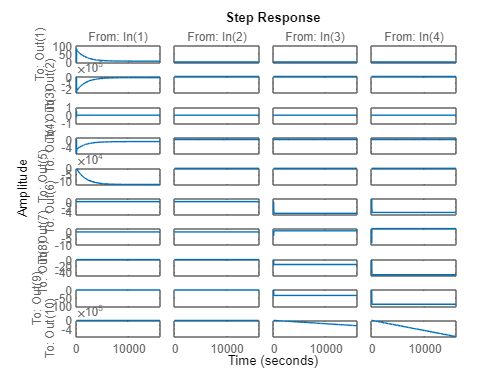

step(sys_ss)

open("Q2_UAV.slx")
out = sim("Q2_UAV.slx")

out =   Simulink.SimulationOutput:

                   tout: [106x1 double] 
                      y: [1x1 timeseries] 

     SimulationMetadata: [1x1 Simulink.SimulationMetadata] 
           ErrorMessage: [0x0 char] 


## System Simulation in SimuLink

We could implement the system in Simulink as follows:

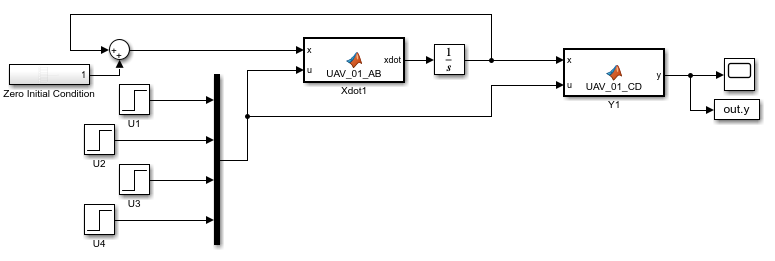

size(out.y.Data)

ans =     10     1   106


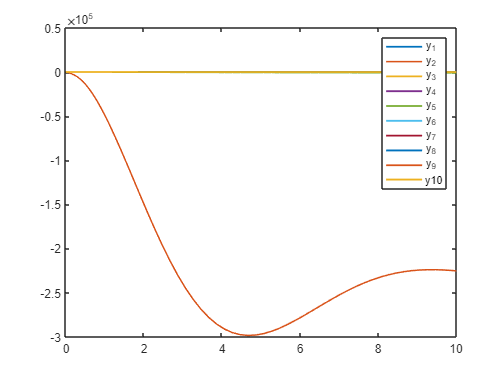

reshaped = reshape(out.y.Data , [10,size(out.y.Data,3)]);
figure
plot(out.tout, reshaped(1,:), LineWidth=1.5)
hold on
plot(out.tout, reshaped(2,:),LineWidth=1.25)
plot(out.tout, reshaped(3,:),LineWidth=1.5)
plot(out.tout, reshaped(4,:),LineWidth=1.5)
plot(out.tout, reshaped(5,:),LineWidth=1.5)
plot(out.tout, reshaped(6,:),LineWidth=1.5)
plot(out.tout, reshaped(7,:),LineWidth=1.5)
plot(out.tout, reshaped(8,:),LineWidth=1.5)
plot(out.tout, reshaped(9,:),LineWidth=1.5)
plot(out.tout, reshaped(10,:),LineWidth=1.5)
legend("y_1", "y_2", "y_3","y_4","y_5","y_6","y_7","y_8","y_9","y10")

You can run the system under different inputs and initial conditions and study system behaviour.

## Controller Design

Since the eigenvalues of the system include instablity, we may want to desing a controller for the system in order to place its poles where we desire. The required condition for such design is that the Controllability Matrix of the system ( `U=ctrb(A,B)` ) is full rank. 

[rankU , numStates]

ans =     10    10


According to$10=10$, the system is controllable and its poles can be placed at any desired location. Considering the obtained poles for the system through unity feedback, unity feedback system poles are stable too.

Let's try this out and see if it is able to place system poles where they are stable or not.

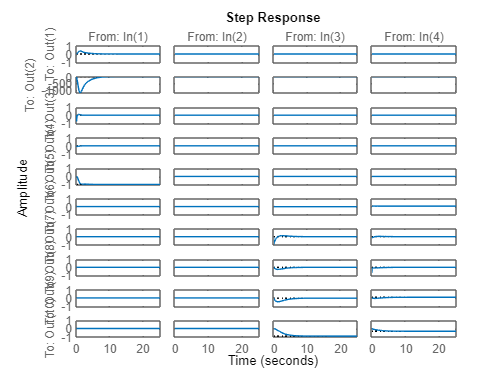

step(sys_lqr)

To conclude, we observed that a negative unity feedback can stabilize the system. In addition, we used `lqr` MATALB command to find an optimal `K` for the feedback gain.

## System Type

We know that the Type of a system equals to the number of poles at the origin. So let's recall the system poles which are the eigenvalues of the matrix `A.`

eig_A

eig_A =    0.0000 + 0.0000i
 -11.6828 +10.0160i
 -11.6828 -10.0160i
  -0.2991 + 0.6752i
  -0.2991 - 0.6752i
  -0.0006 + 0.0000i
 -16.0483 + 0.0000i
  -0.2199 + 0.0000i
  -1.7347 + 3.2696i
  -1.7347 - 3.2696i


Counting poles at the origin:

length(find(eig_A == 0))

ans = 1

So the maximum SystemType of which the system could behave is 1 and since the system is MIMO, Type of the system could vary for different transfer functions of the system due to the zero-pole cancelation throughout system realization.

To study each transfer function (**those that are nonzero**), we need to checkout their denominators.

for o=1:numOutputs  
    for i=1:numInputs
        fprintf("Transfer Function for Output_%d/Input_%d}= \n", o,i)
        eval(simplify(G(o,i)))
        fprintf("-------------------------------------------------------------\n")
    end
end

Transfer Function for Output_1/Input_1}= 


$$ans = \frac{103931830741478864956654892319928043438080000000000\,s^{4}+3121469489518594565991159974410976863606171943043072\,s^{3}+161594549648747308286085174068049629834716785347133440\,s^{2}+3144221676948938625490097397544364164827829108056522752\,s+117557541015456575362180753119740001096451288465408}{324518553658426726783156020576256000000000000000000\,s^{5}+7776892427292001451322264139497629286400000000000000\,s^{4}+81565903709617199449246752037131804412843183308800000\,s^{3}+50154898283829661681674033328966432400876136038400000\,s^{2}+41941713408875204174864245070215176257391715942400000\,s+24147242407981903647129354946849364809823027200000}$$

-------------------------------------------------------------


Transfer Function for Output_1/Input_2}= 


ans = 0

-------------------------------------------------------------


Transfer Function for Output_1/Input_3}= 


ans = 0

-------------------------------------------------------------


Transfer Function for Output_1/Input_4}= 


ans = 0

-------------------------------------------------------------


Transfer Function for Output_2/Input_1}= 


$$ans = -\frac{240635890362669980834737314079256269617155442827329536\,s^{4}+64795178390197296510302184839924074924275532142213070848\,s^{3}+292989776323005456016899031005803928871933452859813658624\,s^{2}+5027334507663137336532875535584046627768378323034540343296\,s+222712410648290284725151999644397317569240239563603968}{162259276829213363391578010288128000000000000000000\,s^{5}+3888446213646000725661132069748814643200000000000000\,s^{4}+40782951854808599724623376018565902206421591654400000\,s^{3}+25077449141914830840837016664483216200438068019200000\,s^{2}+20970856704437602087432122535107588128695857971200000\,s+12073621203990951823564677473424682404911513600000}$$

-------------------------------------------------------------


Transfer Function for Output_2/Input_2}= 


ans = 0

-------------------------------------------------------------


Transfer Function for Output_2/Input_3}= 


ans = 0

-------------------------------------------------------------


Transfer Function for Output_2/Input_4}= 


ans = 0

-------------------------------------------------------------


Transfer Function for Output_3/Input_1}= 


$$ans = -\frac{5\,s\,\left(10847032656032913342726989987761356800000000000\,s^{3}+86787523591651347868222915805574848734822400000\,s^{2}+53926355164459182935208055833203852942619181056\,s+6222991010580584998857469874099753240756224\right)}{405648192073033408478945025720320000000000000\,s^{5}+9721115534115001814152830174372036608000000000\,s^{4}+101957379637021499311558440046414755516053979136\,s^{3}+62693622854787077102092541661208040501095170048\,s^{2}+52427141761094005218580306337768970321739644928\,s+30184053009977379558911693683561706012278784}$$

-------------------------------------------------------------


Transfer Function for Output_3/Input_2}= 


ans = 0

-------------------------------------------------------------


Transfer Function for Output_3/Input_3}= 


ans = 0

-------------------------------------------------------------


Transfer Function for Output_3/Input_4}= 


ans = 0

-------------------------------------------------------------


Transfer Function for Output_4/Input_1}= 


$$ans = -\frac{54235163280164566713634949938806784000000000000\,s^{3}+433937617958256739341114579027874243674112000000\,s^{2}+269631775822295914676040279166019264713095905280\,s+31114955052902924994287349370498766203781120}{405648192073033408478945025720320000000000000\,s^{5}+9721115534115001814152830174372036608000000000\,s^{4}+101957379637021499311558440046414755516053979136\,s^{3}+62693622854787077102092541661208040501095170048\,s^{2}+52427141761094005218580306337768970321739644928\,s+30184053009977379558911693683561706012278784}$$

-------------------------------------------------------------


Transfer Function for Output_4/Input_2}= 


ans = 0

-------------------------------------------------------------


Transfer Function for Output_4/Input_3}= 


ans = 0

-------------------------------------------------------------


Transfer Function for Output_4/Input_4}= 


ans = 0

-------------------------------------------------------------


Transfer Function for Output_5/Input_1}= 


$$ans = -\frac{-138130989276837620285692822884549121802240000000\,s^{3}+6230805805045134652549546677440033239733924528128\,s^{2}+855186094888287007714920124186827944636989413785600\,s+497564573639544366457109865460479188656926951997440}{50706024009129176059868128215040000000000000000\,s^{5}+1215139441764375226769103771796504576000000000000\,s^{4}+12744672454627687413944805005801844439506747392000\,s^{3}+7836702856848384637761567707651005062636896256000\,s^{2}+6553392720136750652322538292221121290217455616000\,s+3773006626247172444863961710445213251534848000}$$

-------------------------------------------------------------


Transfer Function for Output_5/Input_2}= 


ans = 0

-------------------------------------------------------------


Transfer Function for Output_5/Input_3}= 


ans = 0

-------------------------------------------------------------


Transfer Function for Output_5/Input_4}= 


ans = 0

-------------------------------------------------------------


Transfer Function for Output_6/Input_1}= 


ans = 0

-------------------------------------------------------------


Transfer Function for Output_6/Input_2}= 


ans = 0

-------------------------------------------------------------


Transfer Function for Output_6/Input_3}= 


$$ans = -\frac{4140410611795277515421107229245658922286495825920000000\,s^{2}+45449232118956772681902193922331221347510654611750912000\,s+47757200035707431939096457774898597044934304364761186304}{212676479325586539664609129644855132160000000000000000\,s^{4}+4197723278336696885284189157278292656521216000000000000\,s^{3}+15667766852402643227934405072461101237232730112000000000\,s^{2}+50001543770014169084492277807465680233986354105548800000\,s+10282506429169271134893917852792828363919815754330931200}$$

-------------------------------------------------------------


Transfer Function for Output_6/Input_4}= 


$$ans = \frac{8290757623107770424351172793534553598512332800000000000\,s^{3}+2307297360114481369994350568073823064864019783352320000000\,s^{2}+34598826136752191516162074566940021016164395180401623040000\,s-5536567613950843154647189434284882974988941896190923898880}{26584559915698317458076141205606891520000000000000000000\,s^{4}+524715409792087110660523644659786582065152000000000000000\,s^{3}+1958470856550330403491800634057637654654091264000000000000\,s^{2}+6250192971251771135561534725933210029248294263193600000000\,s+1285313303646158891861739731599103545489976969291366400000}$$

-------------------------------------------------------------


Transfer Function for Output_7/Input_1}= 


ans = 0

-------------------------------------------------------------


Transfer Function for Output_7/Input_2}= 


ans = 0

-------------------------------------------------------------


Transfer Function for Output_7/Input_3}= 


$$ans = -\frac{665677380289085869150226575788396563660800000000000000\,s^{3}+2263426019987942144130696501757483042713108480000000000\,s^{2}+7005625050634536895349920597741769738419636797440000000\,s-174254938031613968416553884297063996819240692744192000}{4253529586511730793292182592897102643200000000000000\,s^{4}+83954465566733937705683783145565853130424320000000000\,s^{3}+313355337048052864558688101449222024744654602240000000\,s^{2}+1000030875400283381689845556149313604679727082110976000\,s+205650128583385422697878357055856567278396315086618624}$$

-------------------------------------------------------------


Transfer Function for Output_7/Input_4}= 


$$ans = -\frac{21301676169250747812807250425228690037145600000000000\,s^{3}+1316311756766515539456665413005594865813956853760000000\,s^{2}+18021325615585722780604482783729725165408866009088000000\,s-529336730053058799787808823497895796100198987666030592}{4253529586511730793292182592897102643200000000000000\,s^{4}+83954465566733937705683783145565853130424320000000000\,s^{3}+313355337048052864558688101449222024744654602240000000\,s^{2}+1000030875400283381689845556149313604679727082110976000\,s+205650128583385422697878357055856567278396315086618624}$$

-------------------------------------------------------------


Transfer Function for Output_8/Input_1}= 


ans = 0

-------------------------------------------------------------


Transfer Function for Output_8/Input_2}= 


ans = 0

-------------------------------------------------------------


Transfer Function for Output_8/Input_3}= 


$$ans = \frac{48915590244884904122860099818316680396800000000000000\,s^{3}+487577417619294537931210269222942689177108480000000000\,s^{2}+98865565511824093847292674153076208681405644800000000\,s-3223361783788641665123083320330447591920841523200000000}{4253529586511730793292182592897102643200000000000000\,s^{4}+83954465566733937705683783145565853130424320000000000\,s^{3}+313355337048052864558688101449222024744654602240000000\,s^{2}+1000030875400283381689845556149313604679727082110976000\,s+205650128583385422697878357055856567278396315086618624}$$

-------------------------------------------------------------


Transfer Function for Output_8/Input_4}= 


$$ans = -\frac{348959567277422394281690659921278300848128000000000000\,s^{3}+5914378963315884981558832237919749465019147878400000000\,s^{2}+5565944245288115231731318551057631545816157960273920000\,s+9791652424214924154417477312206729487610044166963200000}{4253529586511730793292182592897102643200000000000000\,s^{4}+83954465566733937705683783145565853130424320000000000\,s^{3}+313355337048052864558688101449222024744654602240000000\,s^{2}+1000030875400283381689845556149313604679727082110976000\,s+205650128583385422697878357055856567278396315086618624}$$

-------------------------------------------------------------


Transfer Function for Output_9/Input_1}= 


ans = 0

-------------------------------------------------------------


Transfer Function for Output_9/Input_2}= 


ans = 0

-------------------------------------------------------------


Transfer Function for Output_9/Input_3}= 


$$ans = -\frac{663033003480447391233344758792218363918548992000000000\,s^{2}+2237067584791443081410135274603290760936193995571200000\,s+7000280378162967684836535955777054438578320008282112000}{4253529586511730793292182592897102643200000000000000\,s^{4}+83954465566733937705683783145565853130424320000000000\,s^{3}+313355337048052864558688101449222024744654602240000000\,s^{2}+1000030875400283381689845556149313604679727082110976000\,s+205650128583385422697878357055856567278396315086618624}$$

-------------------------------------------------------------


Transfer Function for Output_9/Input_4}= 


$$ans = -\frac{200832151881341012238377237502864974904976998400000000\,s^{2}+8180215417616861407798679418937682609464459940331520000\,s+91611102807429992811288857006753357487376867269174886400}{21267647932558653966460912964485513216000000000000000\,s^{4}+419772327833669688528418915727829265652121600000000000\,s^{3}+1566776685240264322793440507246110123723273011200000000\,s^{2}+5000154377001416908449227780746568023398635410554880000\,s+1028250642916927113489391785279282836391981575433093120}$$

-------------------------------------------------------------


Transfer Function for Output_10/Input_1}= 


ans = 0

-------------------------------------------------------------


Transfer Function for Output_10/Input_2}= 


ans = 0

-------------------------------------------------------------


Transfer Function for Output_10/Input_3}= 


$$ans = \frac{97929011670259578053965919836269994154393600000000000\,s^{3}+976129990073827664938282958984331263732571176960000000\,s^{2}+197928862154671835882279933654458569780174100889600000\,s-6453170291144860613576412807301556079025524729446400000}{2\,s\,\left(4253529586511730793292182592897102643200000000000000\,s^{4}+83954465566733937705683783145565853130424320000000000\,s^{3}+313355337048052864558688101449222024744654602240000000\,s^{2}+1000030875400283381689845556149313604679727082110976000\,s+205650128583385422697878357055856567278396315086618624\right)}$$

-------------------------------------------------------------


Transfer Function for Output_10/Input_4}= 


$$ans = -\frac{1746542634223499083379861752905997895744880640000000000\,s^{3}+29601466711396004332701955350788346072420835131392000000\,s^{2}+27857550947667014012556313980535738179813011137025277952\,s+49007220383195696753988941631348534938986700782723661824}{5\,s\,\left(4253529586511730793292182592897102643200000000000000\,s^{4}+83954465566733937705683783145565853130424320000000000\,s^{3}+313355337048052864558688101449222024744654602240000000\,s^{2}+1000030875400283381689845556149313604679727082110976000\,s+205650128583385422697878357055856567278396315086618624\right)}$$

-------------------------------------------------------------


You can see that the nonzero trasfer funcitons of output_10 are of SystemType 1 and all other nonzero transfer functions are for all other outputs are of System Type 0.

## Singular Values Decomposition

We know that singular values of a matrix `A` are the square roots of the eigenvalues of $A^T A$ or ${\textrm{AA}}^T$. in MATLAB, one could use the command `svd` to obtain these values. Remeber that the correponding decomposition for matrix `A` is as follows:


$$A=\textrm{US}V^T$$


UU

UU =     0.0377         0    0.5000         0    0.0054         0   -0.8602         0   -0.0925         0
   -0.7055         0   -0.0024         0   -0.7071         0   -0.0396         0    0.0272         0
   -0.0446         0   -0.0000         0    0.0005         0    0.1049         0   -0.9935         0
    0.7063         0   -0.0290         0   -0.7066         0    0.0130         0   -0.0307         0
   -0.0001         0    0.8656         0   -0.0287         0    0.4972         0    0.0524         0
         0    0.8875         0    0.4441         0    0.1228         0    0.0092         0   -0.0000
         0   -0.4425         0    0.8938         0   -0.0327         0   -0.0215         0    0.0616
         0    0.1212         0    0.0134         0   -0.9398         0    0.2014         0    0.2479
         0    0.0168         0   -0.0583         0    0.1258         0   -0.4831         0    0.8644
         0   -0.0399         0   -0.0185         0    0.2914         0    0.8518      

VV

VV =     0.0553         0   -0.0189         0   -0.0199         0    0.9981         0   -0.0000         0
    0.0059         0    0.0761         0    0.9969         0    0.0210         0    0.0001         0
    0.0003         0   -0.9969         0    0.0765         0   -0.0174         0    0.0000         0
   -0.9985         0   -0.0008         0    0.0049         0    0.0554         0   -0.0000         0
    0.0000         0    0.0000         0    0.0001         0   -0.0000         0   -1.0000         0
         0    0.0273         0   -0.1854         0   -0.4257         0    0.8852         0         0
         0    0.3886         0   -0.8973         0    0.1744         0   -0.1160         0         0
         0   -0.8180         0   -0.2887         0    0.4613         0    0.1866         0         0
         0    0.4233         0    0.2778         0    0.7587         0    0.4100         0         0
         0         0         0         0         0         0         0         0      

SS

SS =    22.3693         0         0         0         0         0         0         0         0         0
         0   20.5299         0         0         0         0         0         0         0         0
         0         0   19.6690         0         0         0         0         0         0         0
         0         0         0   15.6502         0         0         0         0         0         0
         0         0         0         0   10.5870         0         0         0         0         0
         0         0         0         0         0    1.5847         0         0         0         0
         0         0         0         0         0         0    0.5285         0         0         0
         0         0         0         0         0         0         0    0.2192         0         0
         0         0         0         0         0         0         0         0    0.0000         0
         0         0         0         0         0         0         0         0      

So the singular values of the matrix `A` we have in descending order is:

diag(SS)

ans =    22.3693
   20.5299
   19.6690
   15.6502
   10.5870
    1.5847
    0.5285
    0.2192
    0.0000
         0


## BIBO stability

As mentioned earlier, eigenvalues of the system dynamics matrix `A` show that the system is **Bounded-Input-Bounded_Output**. This is also demonstrated in the section that system is simulated in Simulink if you run the system under various inputs.

## Model Reduction - Method 1

Following the book instructions to reduce the model using method one "Model Separation" provides us with following results.

Az, Bz, Cz

Az =    0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i -11.6828 +10.0160i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i -11.6828 -10.0160i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i  -0.2991 + 0.6752i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i  -0.2991 - 0.6752i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i  

Bz = 1.0e+02 *

   0.0000 + 0.0000i   0.0000 + 0.0000i  -0.1569 + 0.0000i  -0.4766 + 0.0000i
  -0.0157 + 1.2827i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
  -0.0157 - 1.2827i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
  -0.4758 - 0.3951i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
  -0.4758 + 0.3951i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.7595 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   1.5783 + 0.0000i   0.0268 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   0.2393 + 0.0000i   0.6572 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0297 + 0.2841i   0.2364 - 2.2835i
   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0297 - 0.2841i   0.2364 + 2.2835i


Cz = 1.0e+03 *

   0.0000 + 0.0000i   0.0000 - 0.0000i   0.0000 + 0.0000i   0.0003 + 0.0004i   0.0003 - 0.0004i  -0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.1251 + 0.0286i   0.1251 - 0.0286i  -1.0463 - 1.1826i  -1.0463 + 1.1826i   0.0017 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i  -0.0002 + 0.0005i  -0.0002 - 0.0005i   0.0000 + 0.0000i   0.0000 - 0.0000i  -0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 - 0.0000i   0.0000 + 0.0000i   0.0000 - 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 - 0.0000i  -0.0009 + 0.0000i  -0.0009 + 0.0000i  -0.0010 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 

Eigenvalues of matrix `A` had been obtained earlier:

eig_A

eig_A =    0.0000 + 0.0000i
 -11.6828 +10.0160i
 -11.6828 -10.0160i
  -0.2991 + 0.6752i
  -0.2991 - 0.6752i
  -0.0006 + 0.0000i
 -16.0483 + 0.0000i
  -0.2199 + 0.0000i
  -1.7347 + 3.2696i
  -1.7347 - 3.2696i


We could see that none of the system modes could be assumed as nondominant. The most probable modes to be dropped off the system are $-11\ldotp 6828\pm 10\ldotp 0160$ and -16.0483. So we are expecting to reduce the system from $n=10$ to $q=7$.

According to the following equations, we could separate the system dynamics.

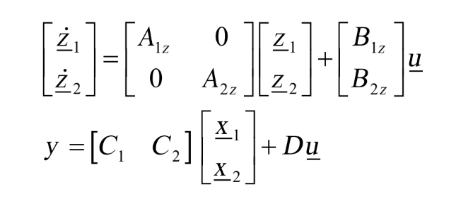

And a whole bunch of steps will lead to:

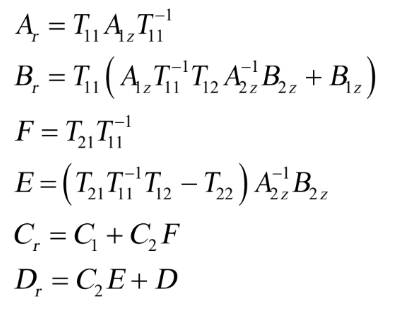

where they all present:

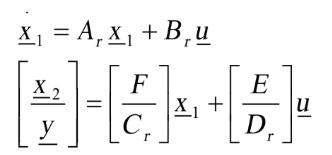

The following results are obtained:

Ar

Ar = 1.0e+02 *

   0.1968 + 0.0000i  -3.5381 - 0.0000i   0.0001 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0113 + 0.0000i  -0.2030 - 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.3515 + 0.0000i  -6.1303 - 0.0000i   0.0002 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i  -0.0104 - 0.0000i  -0.1681 - 0.0000i   0.0989 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0061 - 0.0000i  -0.0277 - 0.0000i   0.0006 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i  -0.0019 + 0.0000i   0.0007 + 0.0000i   0.0011 - 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i  -0.0000 + 0.0000i   0.0100 + 0.0000i   0.0000 - 0.0000i   0.0000 + 0.0000i


Br

Br =   -2.0893 + 0.0454i   0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i
  -0.2354 + 0.0028i   0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i
  -6.5641 + 0.2390i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i  -8.9281 - 0.1813i   5.1502 - 0.0031i
   0.0000 + 0.0000i   0.0000 + 0.0000i   5.8658 - 0.0260i -82.1358 - 0.0004i
   0.0000 + 0.0000i   0.0000 + 0.0000i  -9.7674 + 0.0004i  -0.1660 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   0.3520 + 0.0094i   0.0060 + 0.0002i


Cr

Cr = 1.0e+03 *

  -0.0000 - 0.0000i   0.0005 + 0.0007i   0.0003 - 0.0004i  -0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
  -0.2606 + 0.0589i   3.5440 - 2.1975i  -1.0465 + 1.1826i   0.0017 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0005 + 0.0011i  -0.0079 - 0.0185i   0.0000 - 0.0000i  -0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
  -0.0001 - 0.0000i   0.0012 + 0.0006i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
  -0.0000 + 0.0001i  -0.0008 - 0.0009i  -0.0009 + 0.0000i  -0.0010 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i   0.0001 - 0.0000i   0.0001 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0002 - 0.0000i   0.0001 - 0.0000i  -0.0003 + 0.0000i  -0.0002 - 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   0.000

F

F =   -0.0121 + 0.0000i   0.6058 - 0.0000i  -0.0001 - 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
  -2.0717 - 0.0000i  36.0963 + 0.0000i  -0.0011 - 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i  -0.1868 + 0.0000i   0.0165 + 0.0000i   0.1140 - 0.0000i   0.0000 + 0.0000i


E

E = 1.0e+02 *

  -0.0652 - 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   1.5139 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i  -0.0976 - 0.0000i  -0.0017 - 0.0000i


Hence, the system is reduced from order of 10 to 7 and three nondominant poles are dropped off the system main dynamics.

## Model Reduction - Method 2

Following the book instructions to reduce the model using method one "Residuals" provides us with following results.

Azz

Azz =   -1.7347 - 3.2696i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i  -0.1145 - 4.3328i   0.0015 + 0.2829i   1.0022 + 0.5634i
   0.0000 + 0.0000i  -0.0043 + 0.0093i   0.0402 + 0.0178i  -0.0001 - 0.0002i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0021 + 0.0008i   0.0037 - 0.0083i   0.0002 - 0.0001i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i  -0.2557 - 0.5924i  -0.0322 - 0.0143i  -0.2990 - 0.6750i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i  -1.6520 + 3.0636i   0.1156 - 0.2010i  -1.6659 - 0.7714i
   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i  -1.0578 + 1.9624i   0.0735 - 0.1287i  -1.0671 - 0.4942i
   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.5727 + 0.2569i  -0.0376 - 0.0040i  -0.3642 + 0.3114i


Bzz

Bzz = 1.0e+02 *

   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0658 + 0.0000i  -0.4695 - 0.0000i
  -0.9672 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.2020i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.7735 - 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i  -0.0901 - 0.0000i   0.6466 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i  -0.0576 + 0.0000i   0.4690 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 - 0.1595i  -0.0000 + 1.1412i


Czz

Czz = 1.0e+03 *

   0.0000 + 0.0000i   0.0003 + 0.0000i   0.0000 - 0.0015i  -0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i  -1.0463 + 0.0000i   0.0000 + 4.7303i   0.0017 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 - 0.0001i  -0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i  -0.0009 + 0.0000i   0.0000 + 0.0000i  -0.0010 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i  -0.0000 + 0.0000i   0.0001 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   0.00


eig_A

eig_A =    0.0000 + 0.0000i
 -11.6828 +10.0160i
 -11.6828 -10.0160i
  -0.2991 + 0.6752i
  -0.2991 - 0.6752i
  -0.0006 + 0.0000i
 -16.0483 + 0.0000i
  -0.2199 + 0.0000i
  -1.7347 + 3.2696i
  -1.7347 - 3.2696i


eig_Azz

eig_Azz =   -1.7347 - 3.2696i
  -0.2991 - 0.6752i
  -0.0006 + 0.0013i
  -0.0000 - 0.0000i
  -1.7224 + 3.2463i
  -0.2198 + 0.0000i
  -0.0006 - 0.0000i


we can see that all the dominant poles of the system are almost preserved and the system is reduced from order of 10 to 7. Note that the system responseness would not be exactly the same.